% This script simulates an audiogram

frequencies = [250, 500, 1000, 2000, 3000, 4000, 6000];
dBValuesAudiogram = [-40, -40, -40, -40, -40, -40, -40]; 


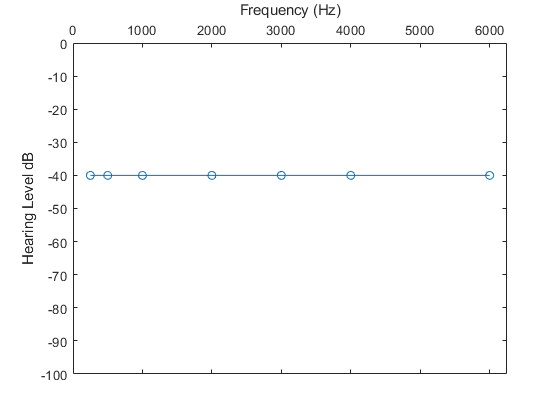

% Plot Audiogram 
plot(frequencies, dBValuesAudiogram,'-o')
xlim([0 6250])
ylim([-100 0])
xlabel('Frequency (Hz)')
ylabel('Hearing Level dB')
set(gca,'xaxisLocation','top')

%insertionGainNAL_NL
dBValuesAudiogram = dBValuesAudiogram*-1;
PTA = (dBValuesAudiogram(2) + dBValuesAudiogram(3) + dBValuesAudiogram(4))/3;
X = 0.15*PTA;
C = [-17, -8, 1, -1, -2, -2, -2];
insertionGain = zeros(1, length(dBValuesAudiogram));

for i = 1:length(frequencies)
    insertionGain(1, i) = X + 0.31.*dBValuesAudiogram(i) + C(i);
end

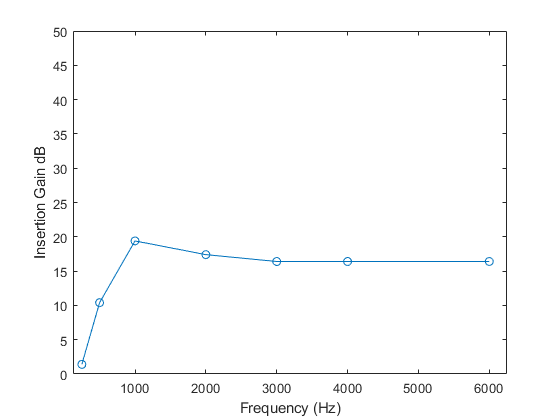

% Plot insertion Gain graph
% Plot Audiogram 
plot(frequencies, insertionGain,'-o')
xlim([125 6250])
ylim([0 50])
xlabel('Frequency (Hz)')
ylabel('Insertion Gain dB')